# Script for paper part 1

author: Raphël Nussbaumer [rafnuss@gmail.com](http://rafnuss@gmail.com)

## Setup

Add general path

addpath(genpath('../functions'))

Add process data 

load("../data/processedDataStudyPressure.mat")

Compute altitude and pressure at location

scriptAltPres()

set color

col = [42,71,94;126 71 149;38 38 38;5 102 47;135 53 19]/255;

## Data illustration

tblLog

tblLog = 16×35 table
    Usable     GDL_ID               LatinName                     CommonName            mass    wingSpan      DataFileName       TwilightShiftK    UTC_Attached    LongitudeAttached    LatitudeAttached    UTC_Removed    LongitudeRemoved    LatitudeRemoved    DEMAttached    UTC_FirstData    UTC_LastData    SubsetStart     SubsetEnd     CalibFirstStart    CalibFirstEnd    CalibSecondStart    CalibSecondEnd    bndy_N    bndy_S    bndy_W    bndy_E                 Color                  StudyPres

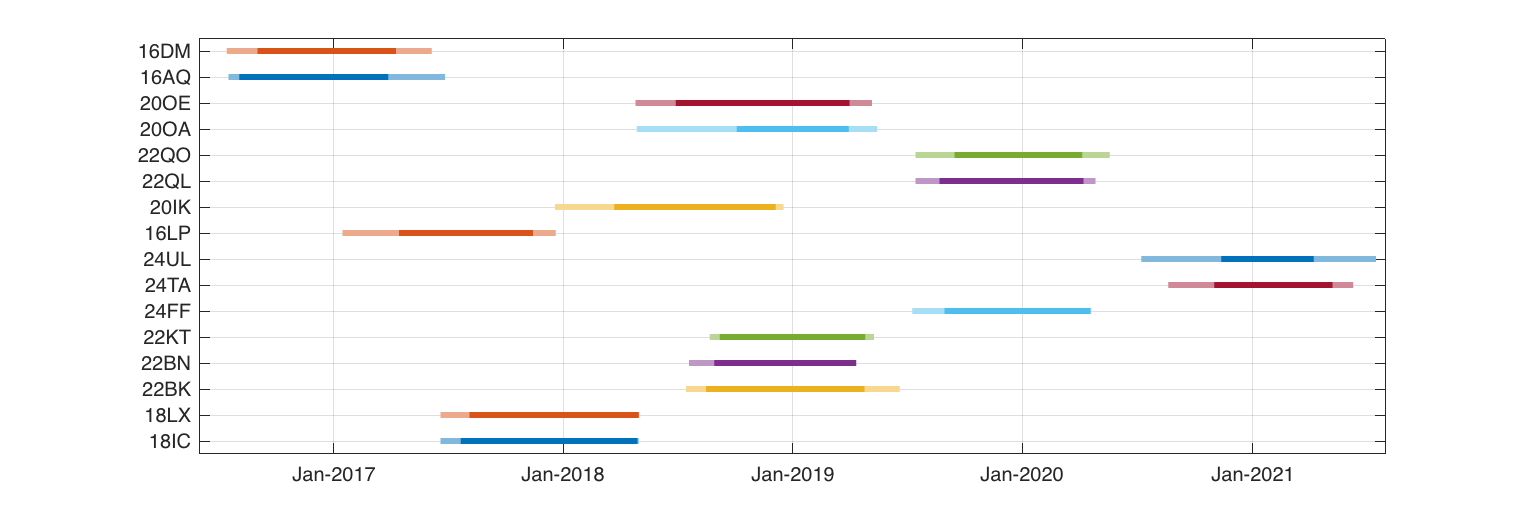

figure('position',[0 0 900 300]); hold on
for lt=1:height(tblLog)
    plot([raw{lt}.light.date(1) raw{lt}.light.date(end)],[lt lt],'linewidth',3,'color',colorder(lt,:));
    plot(raw{lt}.calib.first_period,[lt lt],'linewidth',3,'Color',colorder(lt,:)+ (1-colorder(lt,:))/2)
    plot(raw{lt}.calib.second_period,[lt lt],'linewidth',3,'Color',colorder(lt,:)+ (1-colorder(lt,:))/2)
end
yticks(1:height(tblLog));yticklabels([tblLog.GDL_ID  tblLog.CommonName]); ylim([0.5 height(tblLog)+.5]); grid on; datetick('x','mmm-yyyy')
xlim([datetime('2016-06-01') datetime('2021-08-01')]);

Figure 1

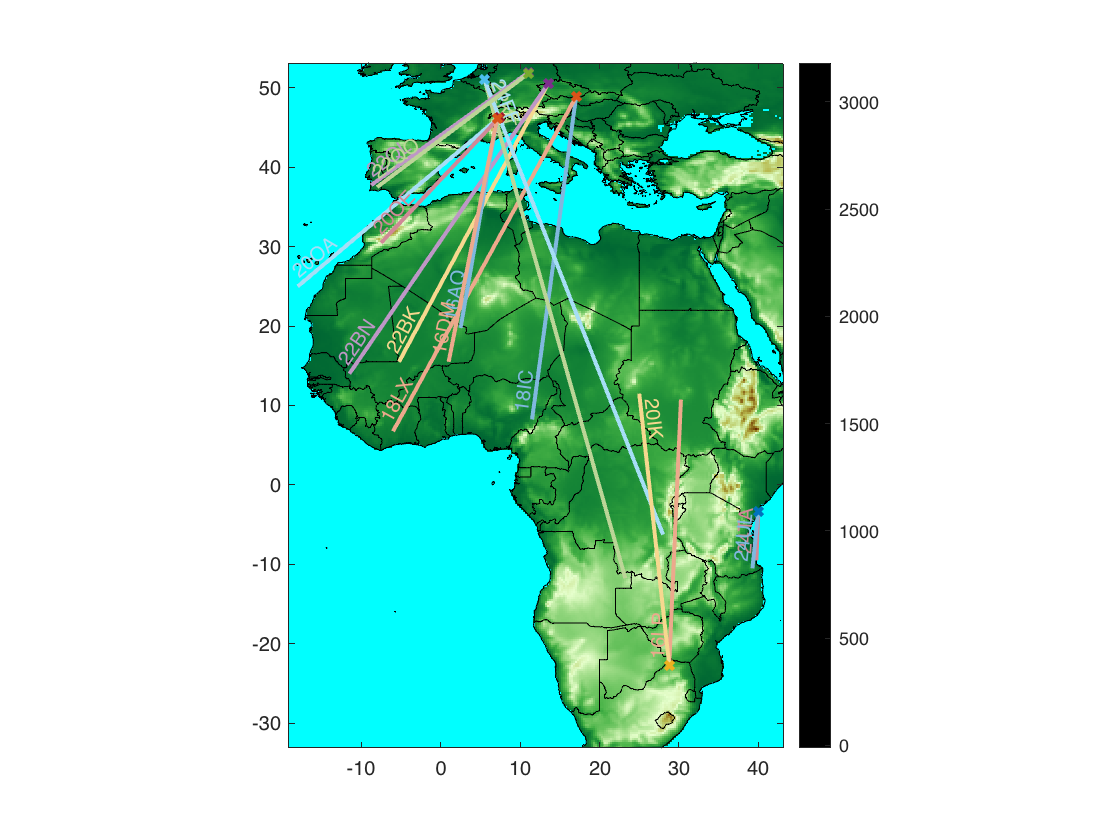

figure; 
% h = worldmap([glat(1) glat(end)],[glon(1) glon(end)]); 
% setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
tmp = geoDEM; tmp(mask_water_g)=-10;
tmp(tmp<30&glon'>20&glat>35)=-100;
tmp(tmp>-100&tmp<0&~mask_water_g)=0;
imagesc(glon,glat,tmp);
axis tight equal; ax=axis;
borders('countries','k');
demcmap([-1 max(geoDEM(:))],256); axis(ax);
colorbar; set(gca,'ydir','normal')

for lt=1:height(tblLog)
   id_wintering=sta{lt}.status=="wintering";
   [max_lat,id_pos_lat]=max(pres_prob{lt}(:,:,id_wintering));
   [~,id_pos_lon] = max(max_lat);

   h=plot([tblLog.LongitudeAttached(lt) lon{lt}(id_pos_lon)],[tblLog.LatitudeAttached(lt) lat{lt}(id_pos_lat(id_pos_lon))],'Color',colorder(lt,:)+ (1-colorder(lt,:))/2,'linewidth',2);
   label(h,tblLog.GDL_ID{lt},'slope')
   plot(tblLog.LongitudeAttached(lt),tblLog.LatitudeAttached(lt),'x','linewidth',2,'color',colorder(lt,:));
   %plot(lon{lt}(id_pos_lon),lat{lt}(id_pos_lat(id_pos_lon)),'o','linewidth',2,'color',colorder(lt,:));
end

Pressure resolution

table(tblLog.GDL_ID,  cellfun(@(x) diff(x.pressure.date(1:2)),raw),'VariableNames',{'GDL_ID','Pressure resolution'})

ans = 16×2 table
     GDL_ID     Pressure resolution
    ________    ___________________

    {'18IC'}         00:30:00      
    {'18LX'}         00:30:00      
    {'22BK'}         00:30:00      
    {'22BN'}         00:30:00      
    {'22KT'}         00:05:00      
    {'24FF'}         00:05:00      
    {'24TA'}         00:05:00      
    {'24UL'}         00:10:00      
    {'16LP'}         00:30:00      
    {'20IK'}         00:05:00      
    {'22QL'}         00:05:00      
    {'22QO'}         00:05:00      
    {'20OA'}         00:05:00      
    {'20OE'}         00:05:00      
    {'16AQ'}         00:15:00      
    {'16DM'}         00:15:00      


status = unique(sta{1}.status);
status_occ = nan(height(tblLog),numel(status));
mig_duration = nan(height(tblLog),2);
mig_distance = nan(height(tblLog),1);
nb_sta = nan(height(tblLog),1);
flight_duration = nan(height(tblLog),1);
for lt=1:height(tblLog)

    id_wintering=sta{lt}.status=="wintering";
    id_retrieval=sta{lt}.status=="retrieval";
    id_equipment=sta{lt}.status=="equipment";

    [max_lat,id_pos_lat]=max(pres_prob{lt}(:,:,id_wintering));
    [~,id_pos_lon] = max(max_lat);
    mig_distance(lt) = round(lldistkm([tblLog.LatitudeAttached(lt) tblLog.LongitudeAttached(lt)],[lat{lt}(id_pos_lat(id_pos_lon)), lon{lt}(id_pos_lon)]));

    tmp = days(sta{lt}.start(id_wintering)-sta{lt}.end(id_equipment));
    if ~isempty(tmp)
    mig_duration(lt,1) = round(tmp);
    end
    tmp = days(sta{lt}.start(id_retrieval)-sta{lt}.end(id_wintering));
    if ~isempty(tmp)
        mig_duration(lt,2) = round(tmp);
    end
    
    flight_duration(lt) = round(hours(sum(sta{lt}.actDuration)));

    [~,Locb] = ismember(sta{lt}.status, status);
    status_occ(lt,:) = histc(Locb, 1:numel(status));
    
    nb_sta(lt) = height(sta{lt});
end
table(tblLog.GDL_ID,mig_duration,mig_distance,flight_duration,nb_sta,'VariableNames',{'GDL_ID','total duration (days)','distance (km)','flight duration (hr)','nb of sta. per.'})

ans = 16×5 table
     GDL_ID     total duration (days)    distance (km)    flight duration (hr)    nb of sta. per.
    ________    _____________________    _____________    ____________________    _______________

    {'18IC'}         111     24              4550                 234                   32       
    {'18LX'}         124     20              5163                 220                   30       
    {'22BK'}          42     33              4241                 226                   46       
    {'22BN'}          81    NaN              4644                 134                   28       
    {'22KT'}          52    115              7192                 462                   69       
    {'24FF'}          72    NaN              6726                 495                   96       
    {'24TA'}          51    

## Light

Check Twilight error during calibration Period

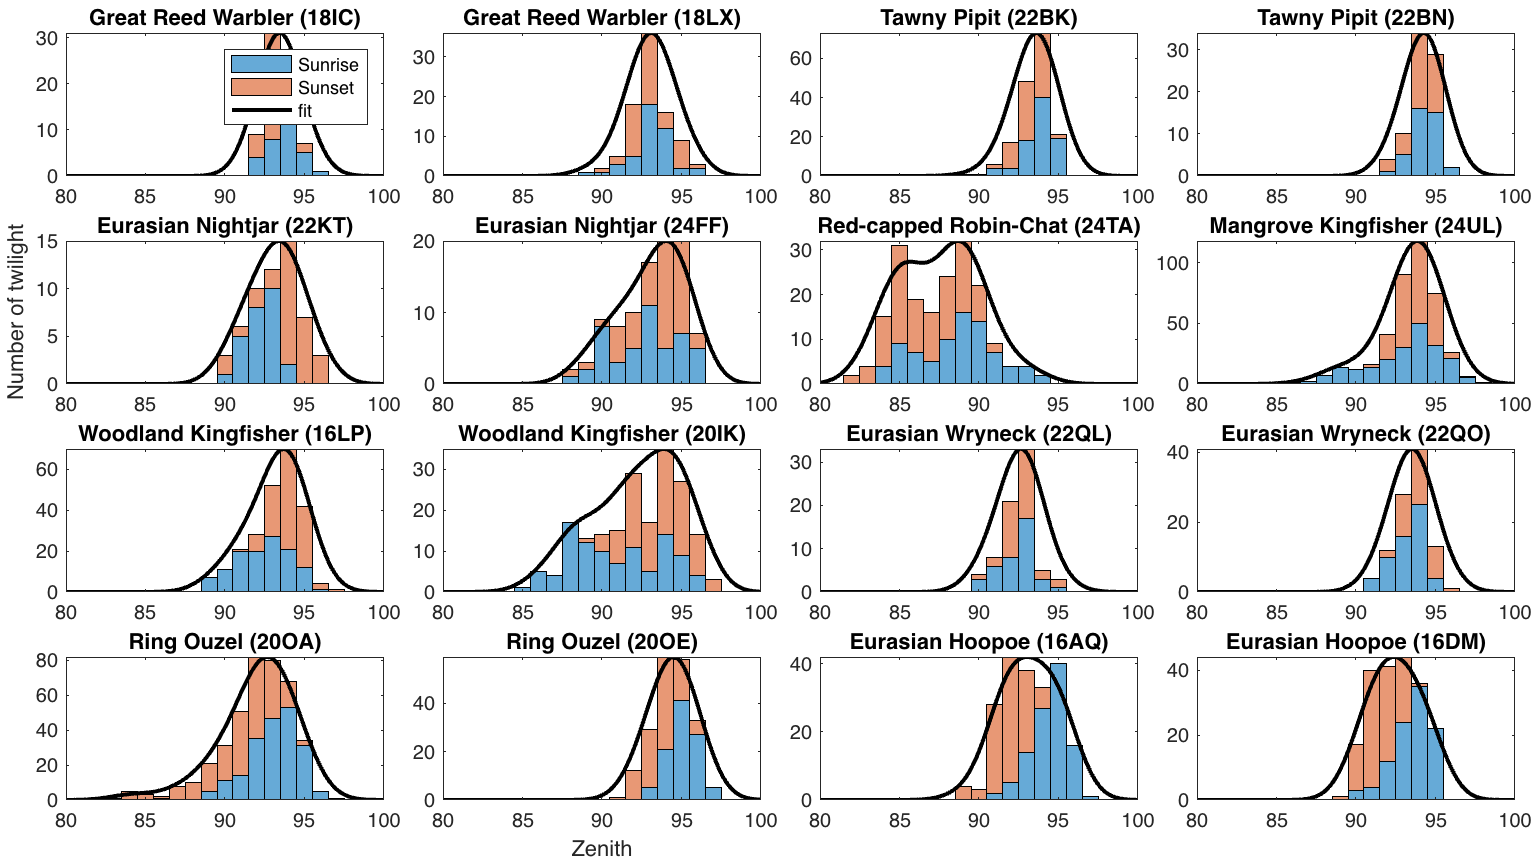

% histogram and fit of Zenith angle
figure('position',[0 0 1600 900]);
tiledlayout('flow','TileSpacing','tight','Padding','tight')
for lt=1:height(tblLog)
    nexttile;
    bar(gE{lt}.bins, [gE{lt}.NRise' gE{lt}.NSet'],1,'stacked','FaceAlpha',0.6);hold on;
    plot(80:.1:100,gE{lt}.pdf(80:.1:100)/max(gE{lt}.pdf(80:.1:100)).*max(sum([gE{lt}.NRise' gE{lt}.NSet'],2)),'-k','LineWidth',2)
    if lt==5, ylabel('Number of twilight'); end
    if lt==14,xlabel('Zenith'); end
    if lt==1,legend('Sunrise','Sunset','fit'); end
    axis tight; xlim([80 100])
    
    title([tblLog.CommonName{lt} ' (' raw{lt}.GDL_ID ')'])
end

% exportgraphics(gcf,'light_zenith_histogram_calib.png','Resolution',300)

Timeserie of zenith angle

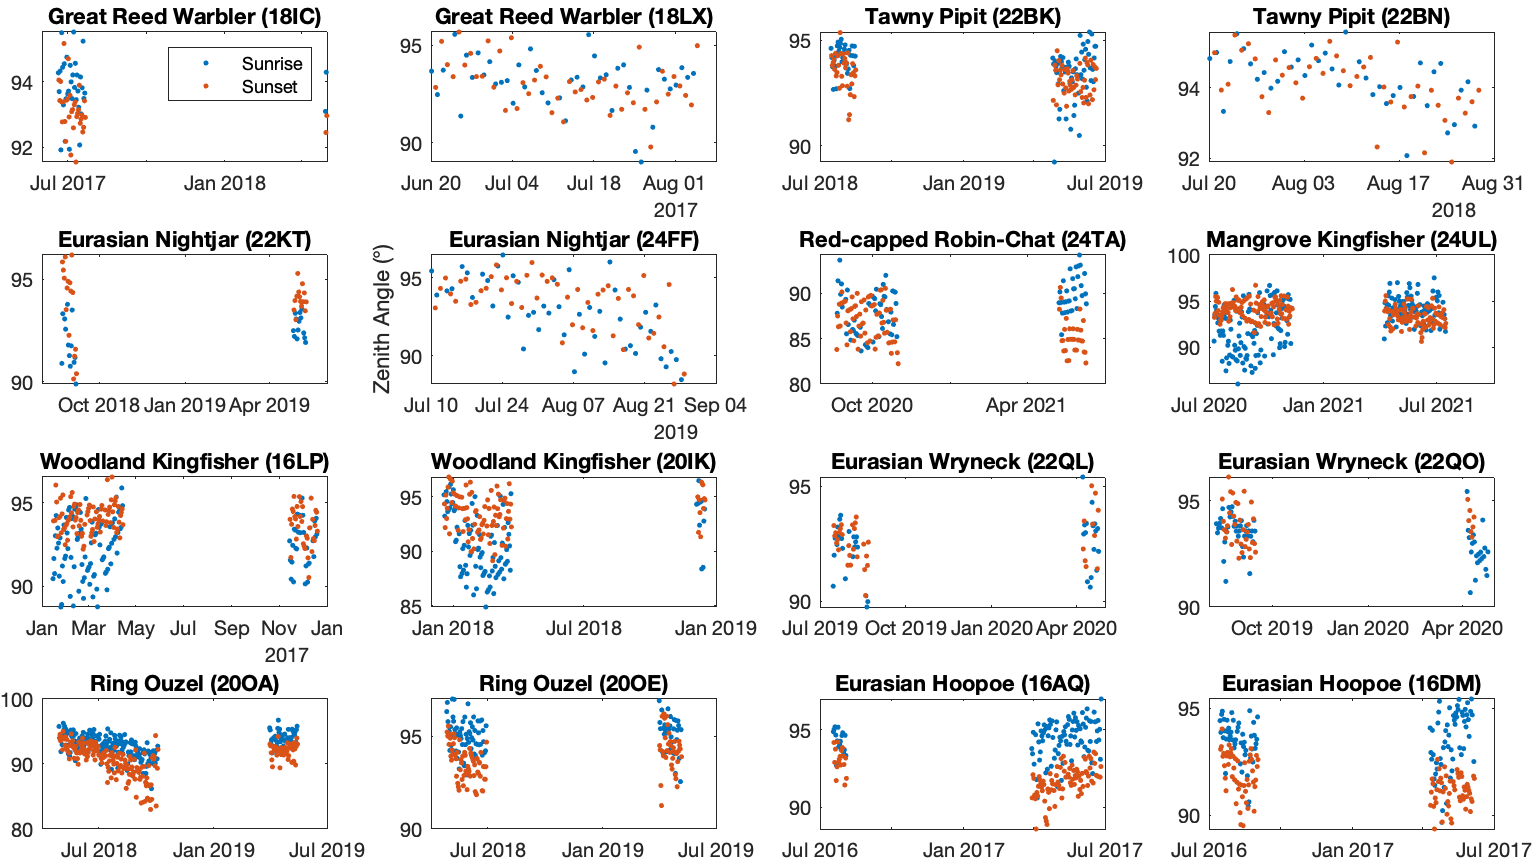

figure('position',[0 0 1600 900]);
tiledlayout('flow','TileSpacing','tight','Padding','tight')
for lt=1:height(tblLog)
    ztmp = gE{lt}.z;
    ztmp(twl{lt}.isOutliar(gE{lt}.id_calib))=nan;
    nexttile; hold on;
    plot(twl{lt}.Twilight(gE{lt}.id_calib'&twl{lt}.Rise), ztmp(twl{lt}.Rise(gE{lt}.id_calib)),'.'); 
    plot(twl{lt}.Twilight(gE{lt}.id_calib'&~twl{lt}.Rise), ztmp(~twl{lt}.Rise(gE{lt}.id_calib)),'.'); 
    if lt==6, ylabel('Zenith Angle (°)'); end
    if lt==13,xlabel(''); end
    if lt==1,legend('Sunrise','Sunset'); end
    title([tblLog.CommonName{lt} ' (' raw{lt}.GDL_ID ')'])
end

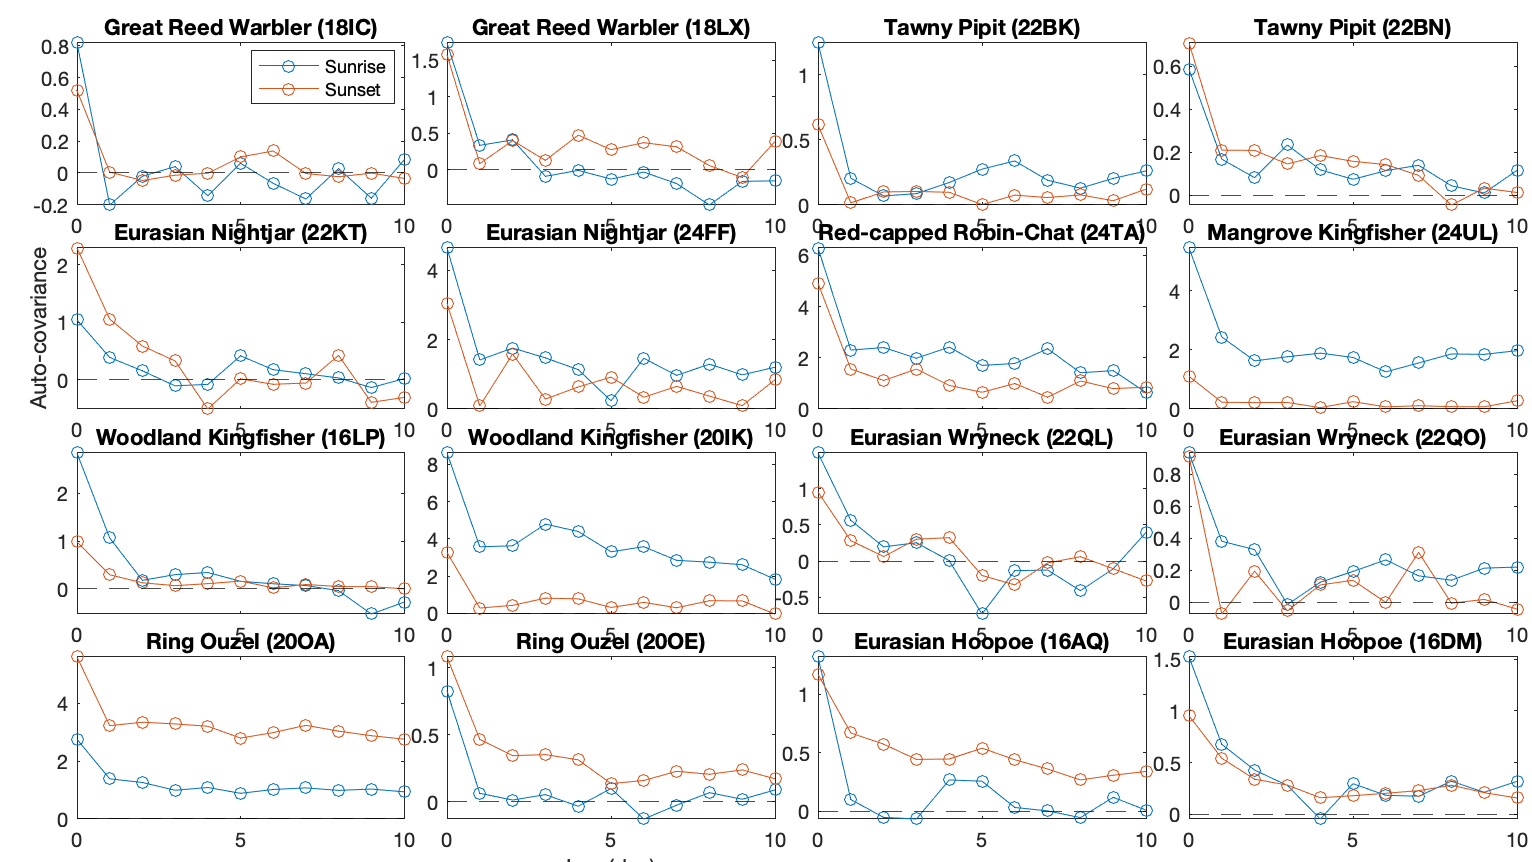

figure('position',[0 0 1600 900]);
ha = tight_subplot(4,ceil(height(tblLog)/4),[.05 .028],[.05 .05],[.05 .01]);
for lt=1:height(tblLog)
    
    tmp = nan(size(twl{lt}.Twilight,1),1);
    tmp(gE{lt}.id_calib) = gE{lt}.z;
    tmp(twl{lt}.isOutliar)=nan;
    tmpR = tmp; tmpR(~twl{lt}.Rise)=nan;
    tmpS = tmp; tmpS(twl{lt}.Rise)=nan;
    acfR = autocorr(tmpR); 
    acfS = autocorr(tmpS);
    
    axes(ha(lt)); 
    plot(0:10,acfR(1:2:end)*var(tmpR,'omitnan'),'o-'); hold on
    plot(0:10,acfS(1:2:end)*var(tmpS,'omitnan'),'o-')
    %ylim([-.2 1.2]); 
    yline(0,'--k'); axis tight
    if lt==5, ylabel('Auto-covariance'); end
    if lt==14,xlabel('Lag (day)'); end
    if lt==1,legend('Sunrise','Sunset'); end
    title([tblLog.CommonName{lt} ' (' raw{lt}.GDL_ID ')'])
end

% exportgraphics(gcf,'light_zenith_autocorrelation_calib.png','Resolution',300)

## Pressure 

time serie at calibration site

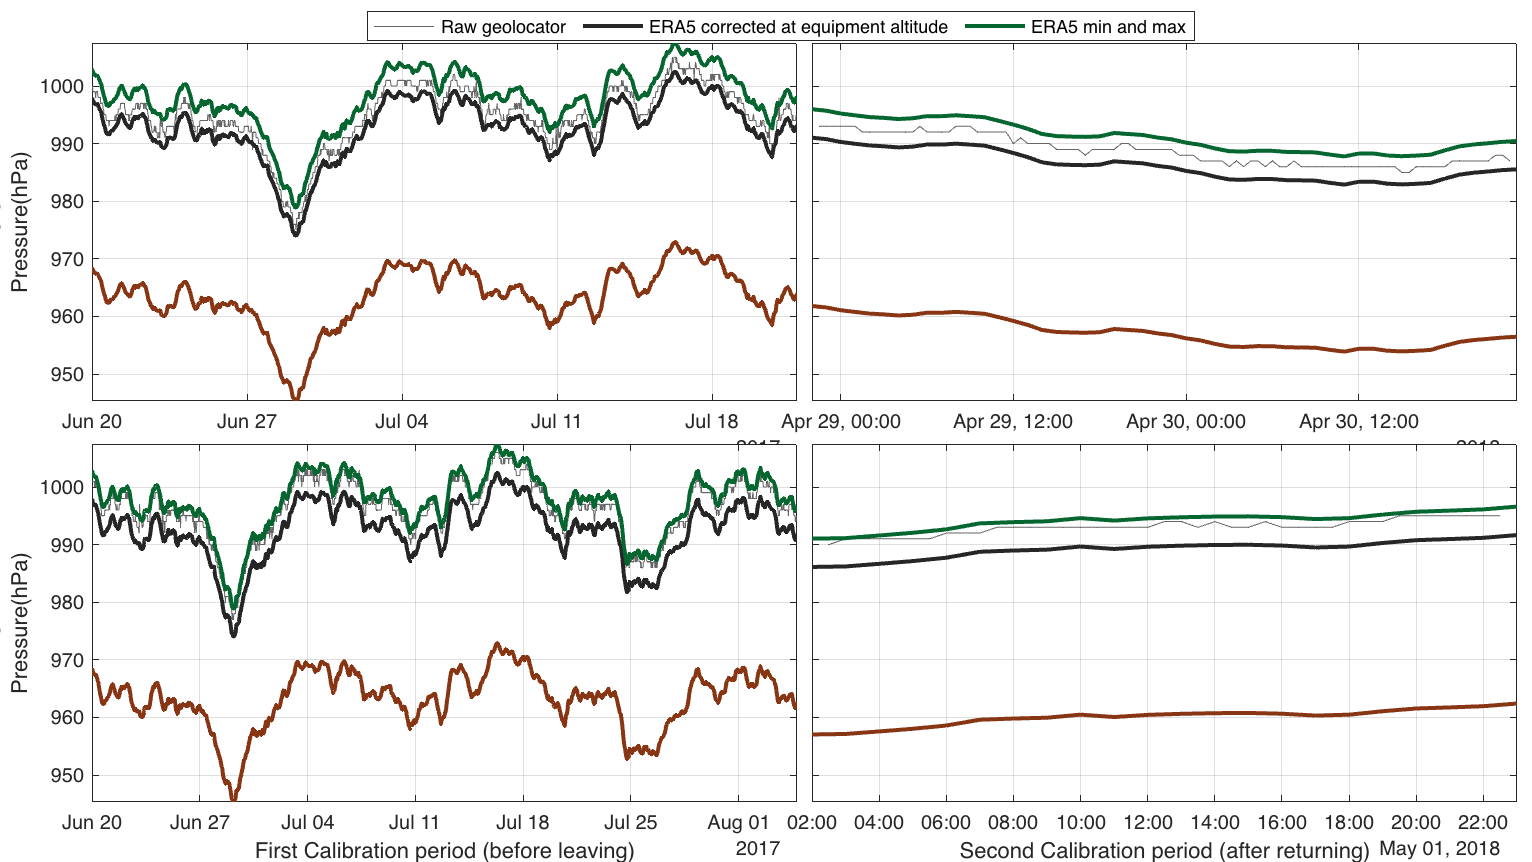

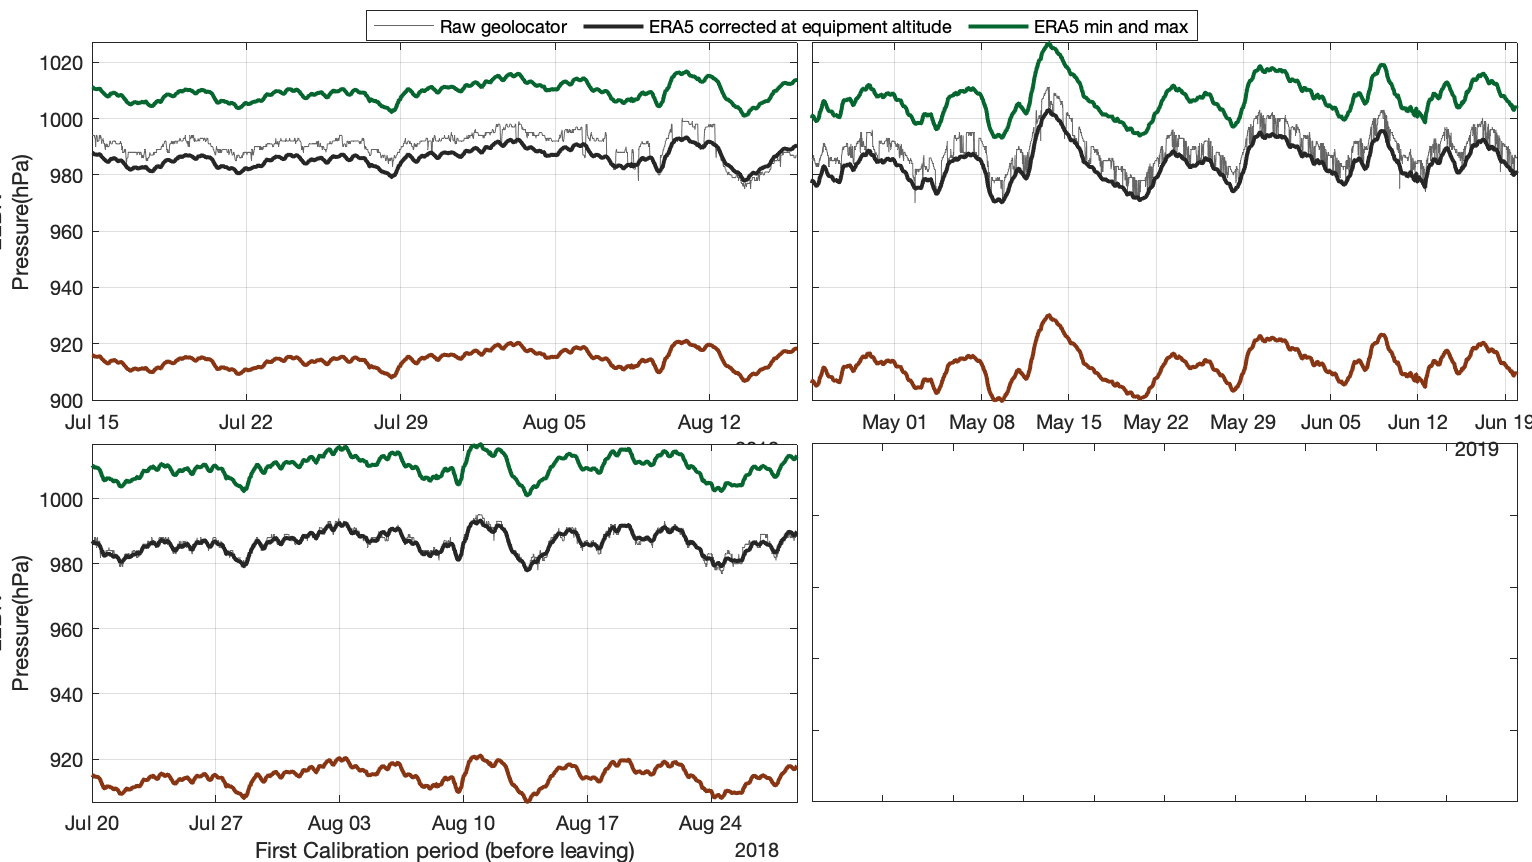

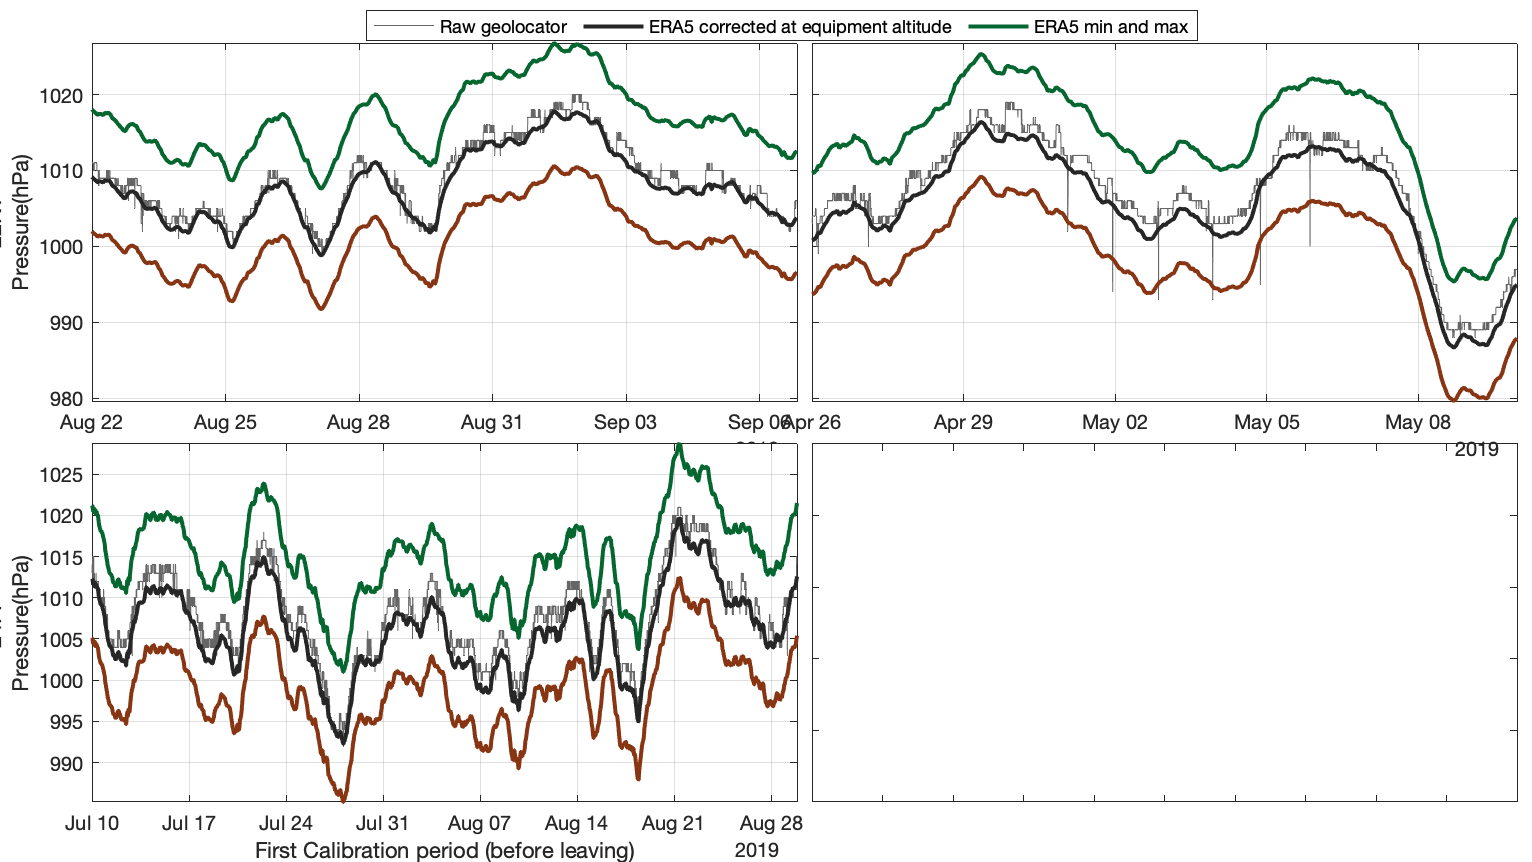

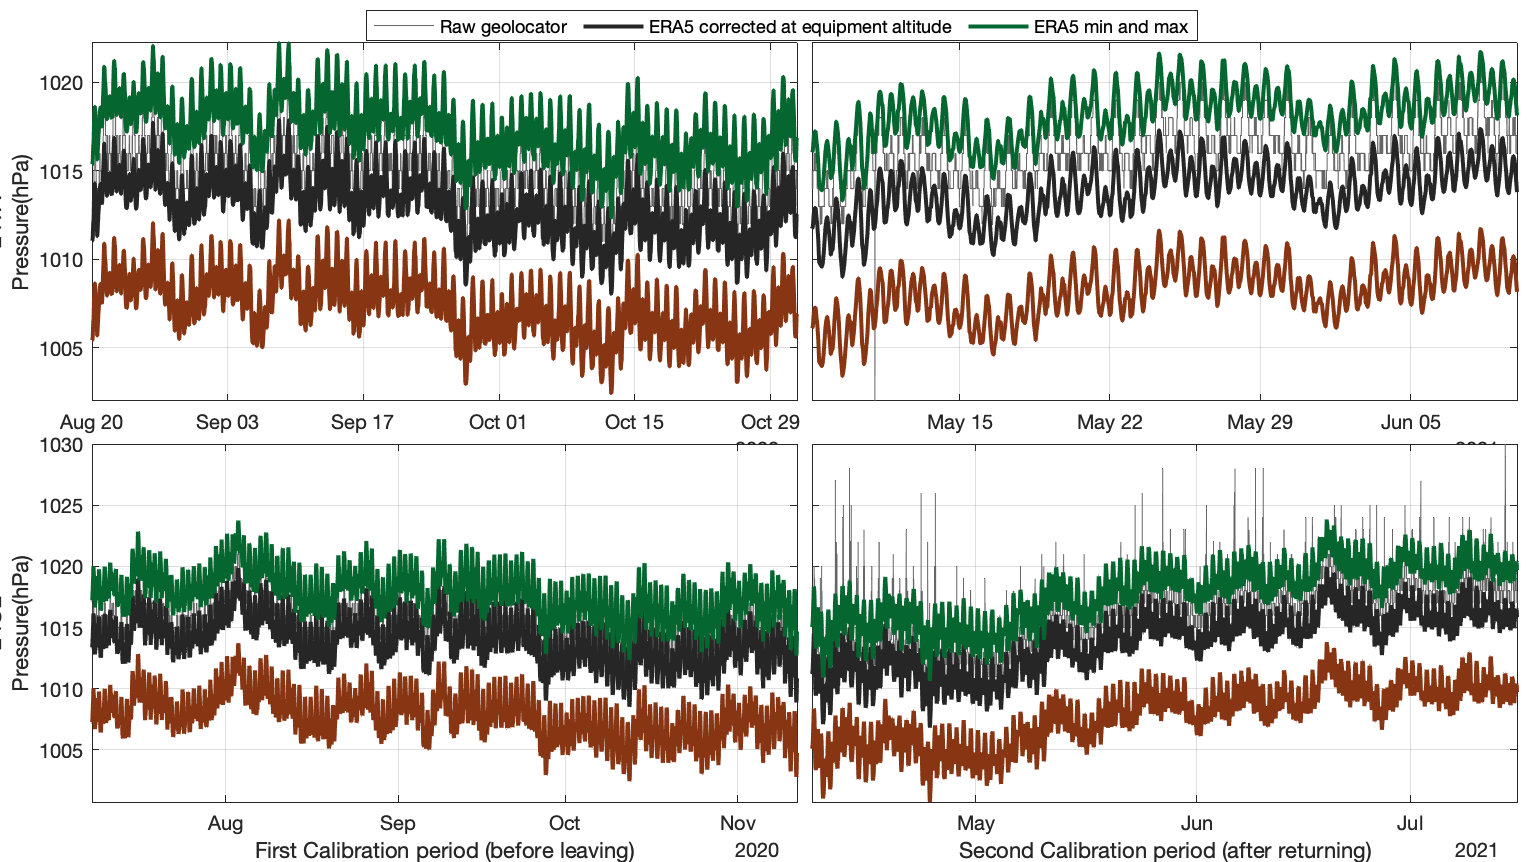

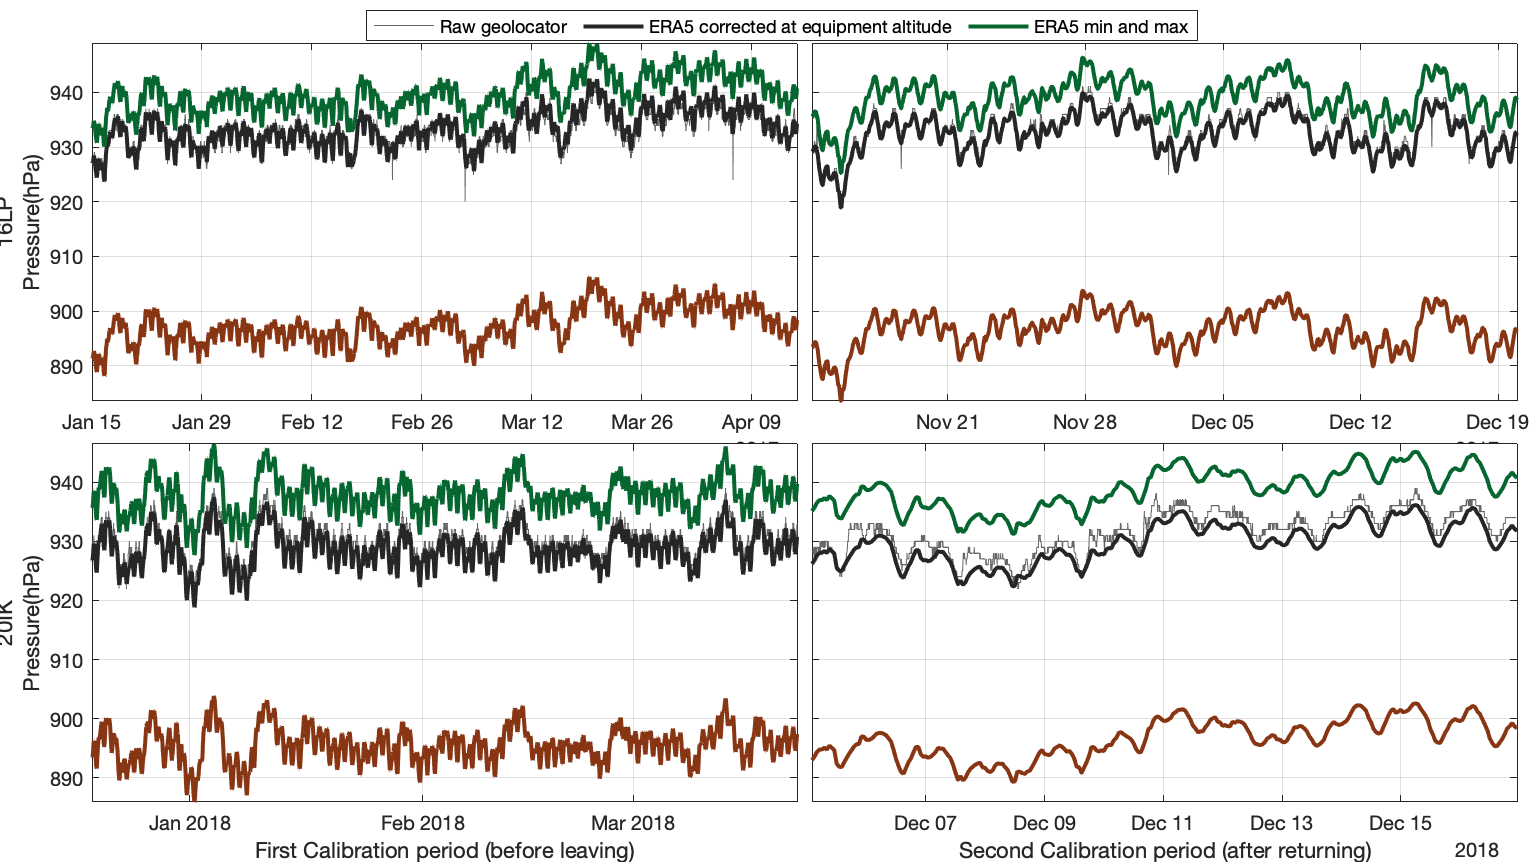

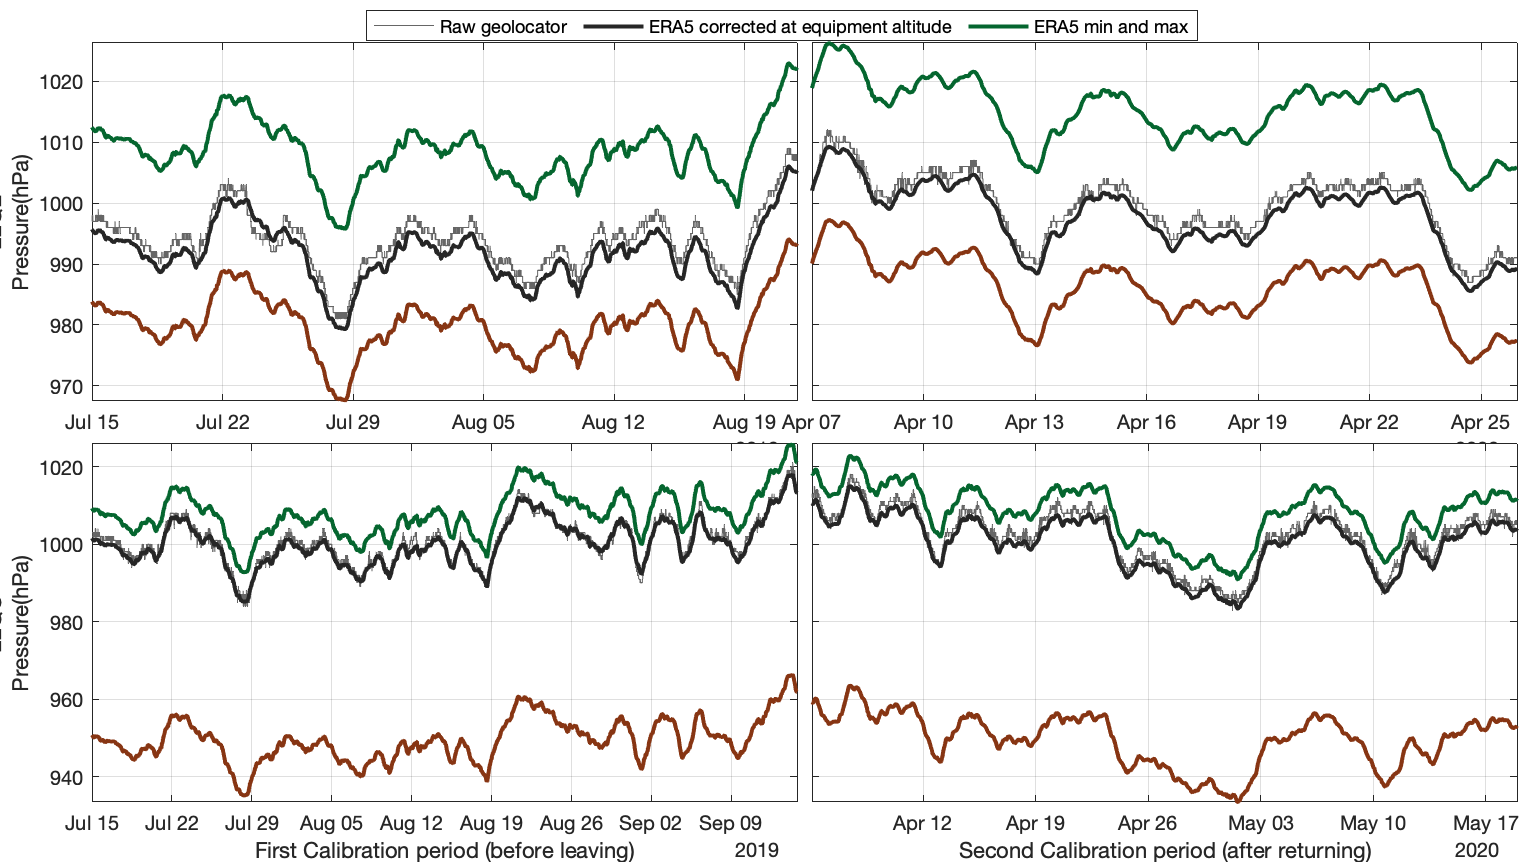

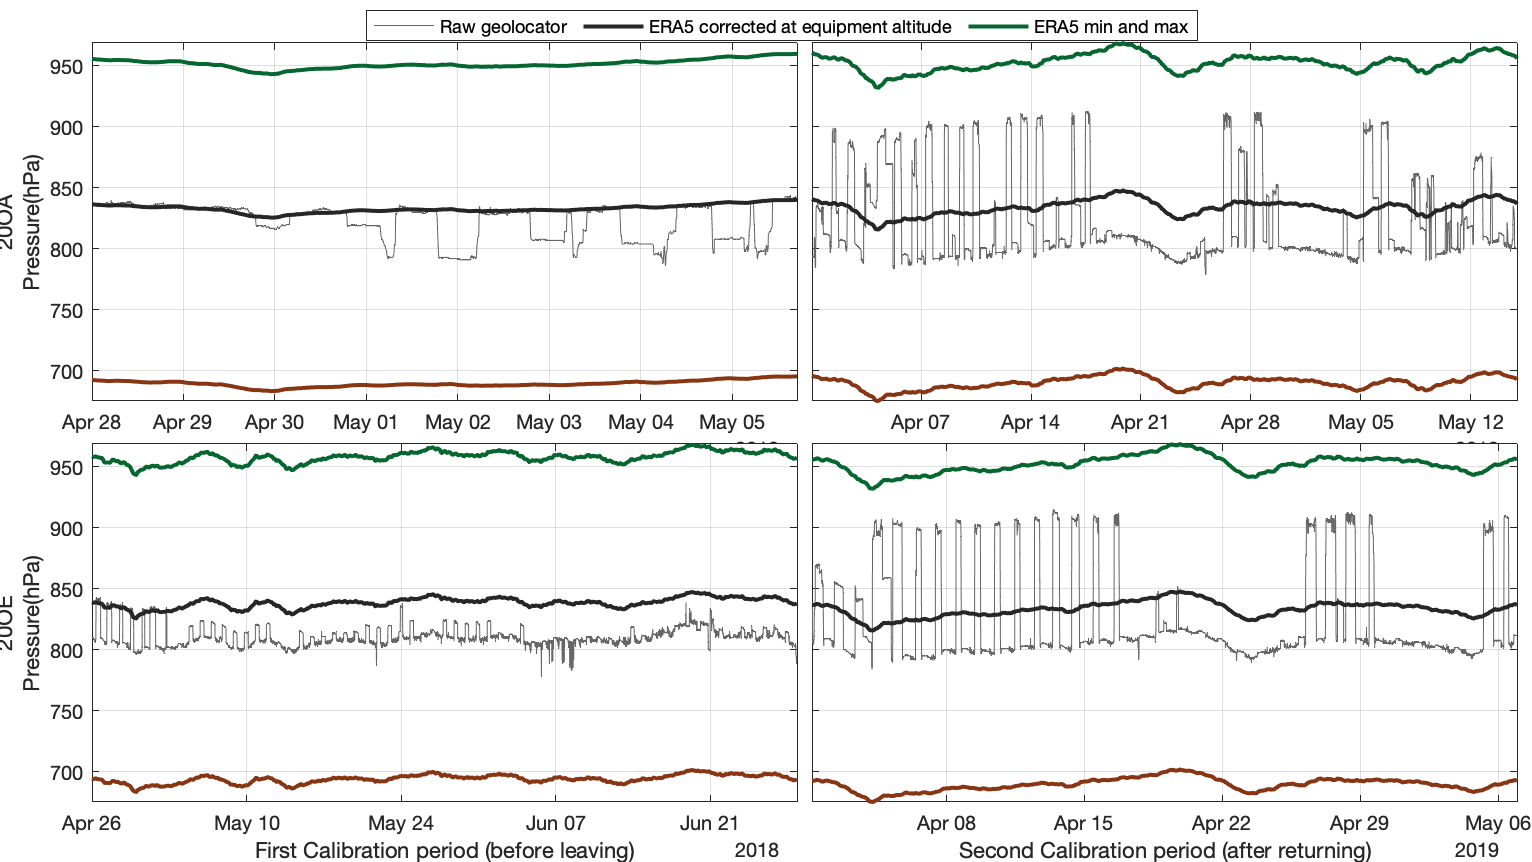

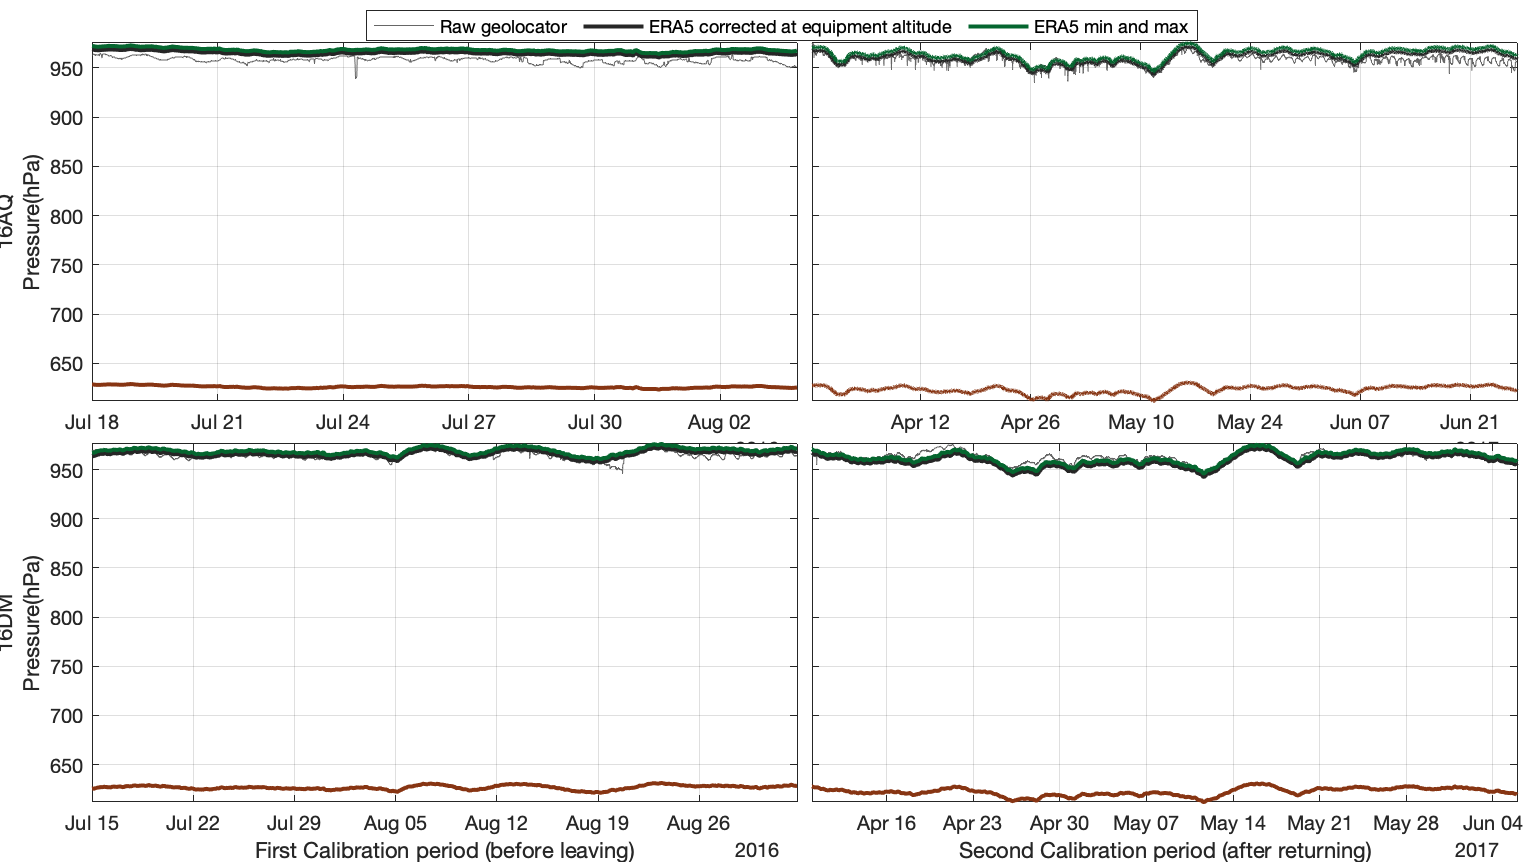

for lt=1:height(tblLog)
    dt = 1./hours(diff(raw{lt}.pressure.date(1:2)));
    if mod(lt,2)==1
        figure('position',[0 0 1200 675], 'Name', [tblLog.CommonName{lt} ' (' raw{lt}.GDL_ID ',' raw{lt+1}.GDL_ID ')' ]);
        ha = tight_subplot(2,2,[.05 .01],[.07 .05],[.06 .01]);
        u=1;
    end
    ss=find(sta{lt}.status=="equipment" | sta{lt}.status=="retrieval");
    for i=1:numel(ss)
        i_s=ss(i);

        pres_gr_att = altitude2pressure(tblLog.DEMAttached(lt)-calibGeoDEM(lt,1), sp{lt}{i_s}.presCalib);
        pres_gr_min = altitude2pressure(calibGeoDEM(lt,2)-calibGeoDEM(lt,1)+dh_margin(1), sp{lt}{i_s}.presCalib);
        pres_gr_max = altitude2pressure(calibGeoDEM(lt,3)-calibGeoDEM(lt,1)+dh_margin(2), sp{lt}{i_s}.presCalib);
        id_t = sp{lt}{i_s}.time(1)<raw{lt}.pressure.date & sp{lt}{i_s}.time(end)>raw{lt}.pressure.date;

        axes(ha(u))
        plot(raw{lt}.pressure.date(id_t),raw{lt}.pressure.obsWithOutliars(id_t),'color',[.4 .4 .4]);  hold on
        % plot(sp{lt}{i_s}.time,sp{lt}{i_s}.pres,'color',col(1,:),'linewidth',2)
        % plot(sp{lt}{i_s}.time,sp{lt}{i_s}.presCalib,'color','r','linewidth',2)
        plot(sp{lt}{i_s}.time,pres_gr_att,'color',col(3,:),'linewidth',2)
        plot(sp{lt}{i_s}.time,pres_gr_min,'color',col(4,:),'linewidth',2)
        plot(sp{lt}{i_s}.time,pres_gr_max,'color',col(5,:),'linewidth',2)

        grid on; box on; axis tight;
        if i_s==1
            ylabel({raw{lt}.GDL_ID ,'Pressure(hPa)'})
        else
            ax_tmp = [min([get(ha(u-1),'ylim') get(ha(u),'ylim')]) max([get(ha(u-1),'ylim') get(ha(u),'ylim')])];
            set(ha(u),'ylim',ax_tmp)
            set(ha(u-1),'ylim',ax_tmp)
            set(ha(u),'yticklabels','');
        end
        
        if mod(lt,2)==1 && i_s==1
            legend({'Raw geolocator', 'ERA5 corrected at equipment altitude', 'ERA5 min and max'},'Position', [.51 .97 0 0],'orientation','horizontal')
        end
        if mod(lt,2)==0
            if i_s==1
                xlabel('First Calibration period (before leaving)')
            else
                xlabel('Second Calibration period (after returning)')
            end
        end
        u=u+1;
    end
    u=3;
    if mod(lt,2)==0
       % exportgraphics(gcf,['pressure_ts_calib_' tblLog.CommonName{lt} '_' raw{lt-1}.GDL_ID '_' raw{lt}.GDL_ID '.png'],'Resolution',300)
    end
    %dynamicDateTicks();
end

Entire time series

for lt=1:height(tblLog)
    dt = 1./hours(diff(raw{lt}.pressure.date(1:2)));
    if mod(lt,2)==1
        figure('position',[0 0 1200 675], 'Name', [tblLog.CommonName{lt} ' (' raw{lt}.GDL_ID ',' raw{lt+1}.GDL_ID ')' ]);
        ha = tight_subplot(2,1,[.05 .028],[.05 .05],[.05 .01]);
        u=1;
    end
    axes(ha(u));u=u+1;

    plot(raw{lt}.pressure.date,raw{lt}.pressure.obsWithOutliars,'color',[.4 .4 .4]);  hold on
    
    for i_s = 1:height(sta{lt})
        
        id_tgr = find(sta{lt}.start(i_s)<spttime & spttime < sta{lt}.end(i_s));
        id_tge = sta{lt}.start(i_s)<raw{lt}.pressure.date & raw{lt}.pressure.date < sta{lt}.end(i_s);
        % pres_ge = movmean(movmedian(raw{lt}.pressure.obs(id_tge),3),dt);
        pres_ge = movmean(raw{lt}.pressure.obs(id_tge),3);
        id_t_gre = ismember(raw{lt}.pressure.date(id_tge),spttime(id_tgr));
        pres_gr = pres_ge(id_t_gre);
        plot(spttime(id_tgr), pres_gr,'LineWidth',2,'color',col(mod(i_s+1,2)+1,:))

        plot(sp{lt}{i_s}.time,sp{lt}{i_s}.pres-nanmean(sp{lt}{i_s}.pres)+nanmean(pres_gr),'color','r')
    end
    ylabel({raw{lt}.GDL_ID ,'Pressure(hPa)'})
    grid on; box on; axis tight;
    % ylabel('Atmospheric Pressure [hPa]'); xlabel('Date');
    if mod(lt,2)==1
        legend({'Raw geolocator', 'Cleaned geolocator per stationary period','ERA5 at best matched location'},'Position', [.51 .97 0 0],'orientation','horizontal')
    else
        % exportgraphics(gcf,['pressure_ts_full_' tblLog.CommonName{lt} '_' raw{lt-1}.GDL_ID '_' raw{lt}.GDL_ID '.png'],'Resolution',300)
    end
end

i_s=1;
for lt=1:height(tblLog)
    stdpres(lt)=std(sp{lt}{i_s}.presCalib);
    stdalt(lt)=std(pressure2altitude(sp{lt}{i_s}.presCalib));
end

Error histogram

figure('position',[0 0 1600 900]);
ha = tight_subplot(4,ceil(height(tblLog)/4),[.05 .028],[.05 .05],[.05 .01]);
for lt=1:height(tblLog)
    e=[];
    dt = 1./hours(diff(raw{lt}.pressure.date(1:2)));
    ss=find(sta{lt}.status=="equipment" | sta{lt}.status=="retrieval");
    for i=1:numel(ss)
        i_s=ss(i);

        pres_ge = movmean(raw{lt}.pressure.obs,3);
        id_t_gre = ismember(raw{lt}.pressure.date,sp{lt}{i_s}.time(1:end-1));
        pres_gr = pres_ge(id_t_gre);

        et=pres_gr'-sp{lt}{i_s}.presCalib(1:end-1);
        e=[e;et(:)-mean(et,'omitnan')];
        % figure; plot(sp{lt}{i_s}.time(1:end-1),et); title(lt)
    end
    axes(ha(lt));
    if true
        histfit(e)
        legend(['S=' num2str(nanstd(e),2)])
        %xlim([-2 2])
    else
        % test for smaller duration: 
        xi=0:24*2;
%         block_size=24.*[.25 .5 1 2 5 10 100];
%         for i_b = 1:numel(block_size)
%             G=repelem(1:ceil(numel(e)/block_size(i_b)),1,block_size(i_b))'; G=G(1:numel(e));
%             me=splitapply(@nanmean,e,G);
%             en = e-me(G);
%             covxi = autocorr(en,xi(end))*var(en,'omitnan');
%             plot(xi/24,covxi,"displayname",num2str(block_size(i_b))); hold on;
%         end
        covxi = autocorr(e,xi(end))*var(e,'omitnan');
        plot(xi/24,covxi); hold on;
        grid on;
        if lt==5, ylabel('Auto-covariance'); end
        if lt==14,xlabel('Lag (days)'); end
        if lt==1, legend(); end
        xlim([0 xi(end)/24]) 
    end
    title([tblLog.CommonName{lt} ' (' raw{lt}.GDL_ID ')'])
end
% exportgraphics(gcf,'pressure_error_autocovariance_calib.png','Resolution',300)
% exportgraphics(gcf,'pressure_error_histogram_calib.png','Resolution',300)

## Altitude

Timeserie of altitude

for lt=1:height(tblLog)
    dt = 1./hours(diff(raw{lt}.pressure.date(1:2)));
    if mod(lt,2)==1
        figure('position',[0 0 1200 675], 'Name', [tblLog.CommonName{lt} ' (' raw{lt}.GDL_ID ',' raw{lt+1}.GDL_ID ')' ]);
        ha = tight_subplot(2,1,[.05 .028],[.05 .05],[.05 .01]);
        u=1;
    end
    axes(ha(u));u=u+1;
    
    for i_s = 1:height(sta{lt})
        if sta{lt}.status(i_s)=="equipment" || sta{lt}.status(i_s)=="retrieval"
           p2=plot(alt{lt}{i_s}.time,alt{lt}{i_s}.altCalib,'-r','linewidth',2); hold on;
        end
        p1=plot(alt{lt}{i_s}.time,alt{lt}{i_s}.alt,'color',col(mod(i_s+1,2)+1,:));
    end
    p3=yline(tblLog.DEMAttached(lt),'--r'); hold on;
    ylabel({raw{lt}.GDL_ID ,'Altitude (m asl)'})
    grid on; box on; axis tight;
    % ylabel('Atmospheric Pressure [hPa]'); xlabel('Date');
    if mod(lt,2)==1
        legend([p1,p2,p3],'Alitude of equipement', 'Altitude according to the best matched location','Altitude according to the equipement location','Position', [.51 .97 0 0],'orientation','horizontal')
    else
        % exportgraphics(gcf,['altitude_ts_' tblLog.CommonName{lt} '_' raw{lt-1}.GDL_ID '_' raw{lt}.GDL_ID '.png'],'Resolution',300)
    end
end

lt=find(tblLog.GDL_ID=="18IC");
i_s=1;
figure;
p2=plot(alt{lt}{i_s}.time,alt{lt}{i_s}.altCalib,'-r','linewidth',2); hold on;
p1=plot(alt{lt}{i_s}.time,alt{lt}{i_s}.alt,'color',col(mod(i_s+1,2)+1,:));
p4=plot(alt{lt}{i_s}.time,alt{lt}{i_s}.alt_basic,'color','g');
p3=yline(tblLog.DEMAttached(lt),'--r'); hold on;
ylabel({raw{lt}.GDL_ID ,'Altitude (m asl)'})
grid on; box on; axis tight; xlim([sta{lt}.start(i_s) sta{lt}.end(i_s)-1])
% ylabel('Atmospheric Pressure [hPa]'); xlabel('Date');
legend([p1,p2,p3,p4],'Alitude of equipement', 'Altitude according to the best matched location','Altitude according to the equipement location','Position', [.51 .97 0 0],'orientation','horizontal')

## Figure 2: method

lt=find(tblLog.GDL_ID == "18IC"); % 22QL 22QO
dt = 1./hours(diff(raw{lt}.pressure.date(1:2))); 

Timeserie

figure; hold on
plot(raw{lt}.pressure.date,raw{lt}.pressure.obsWithOutliars,'color',[.4 .4 .4]); 
for i_s = 1:height(sta{lt})
    id_tgr = find(sta{lt}.start(i_s)<spttime & spttime < sta{lt}.end(i_s));
    id_tge = sta{lt}.start(i_s)<raw{lt}.pressure.date & raw{lt}.pressure.date < sta{lt}.end(i_s);
    pres_ge = movmean(movmedian(raw{lt}.pressure.obs(id_tge),3),dt);
    id_t_gre = ismember(raw{lt}.pressure.date(id_tge),spttime(id_tgr));
    pres_gr = pres_ge(id_t_gre);
    plot(spttime(id_tgr), pres_gr,'LineWidth',2,'color',col(mod(i_s+1,2)+1,:))
end
grid on; box on;
xlim([dateshift(sta{lt}.end(9),'start','day') dateshift(sta{lt}.start(end),'start','day')+1]); 
ylim([650 1050])

DEM

% [DEM,R] = readgeoraster('../data/DEM/export_DEM-0000000000-0000000000.tif');
% DEM = flipud(DEM);
% dem_lat = (R.LatitudeLimits(1)+R.CellExtentInLatitude/2):R.CellExtentInLatitude:(R.LatitudeLimits(2)-R.CellExtentInLatitude/2);
% dem_lon = (R.LongitudeLimits(1)+R.CellExtentInLongitude/2):R.CellExtentInLongitude:(R.LongitudeLimits(2)-R.CellExtentInLongitude/2);
% dlatlon=0.25;
% dl=dlatlon/2+dlatlon*3;
% id_lat_dem=(raw{lt}.calib.lat-dl)<=dem_lat & (raw{lt}.calib.lat+dl)>=dem_lat;
% id_lon_dem=(raw{lt}.calib.lon-dl)<=dem_lon & (raw{lt}.calib.lon+dl)>=dem_lon;
% dem_lon=dem_lon(id_lon_dem);
% dem_lat=dem_lat(id_lat_dem);
% DEM = DEM(id_lat_dem,id_lon_dem);
% save(['../data/DEM/DEM_' raw{lt}.GDL_ID '.mat'],'DEM','dem_lat','dem_lon','dlatlon')
load('../data/DEM/DEM_18IC.mat'); dlatlon=0.25;

[~,id_s]=sort(DEM(:));
[dem_LON,dem_LAT] = meshgrid(dem_lon,dem_lat);

ERA5_gridcell = round([raw{lt}.calib.lon raw{lt}.calib.lat]/dlatlon)*dlatlon;

id_ss=id_s(dem_LON(id_s)>=ERA5_gridcell(1)-dlatlon/2 & dem_LON(id_s)<=ERA5_gridcell(1)+dlatlon/2 & dem_LAT(id_s)>=ERA5_gridcell(2)-dlatlon/2 & dem_LAT(id_s)<=ERA5_gridcell(2)+dlatlon/2);
[id_min_lat,id_min_lon]=ind2sub(size(DEM),id_ss(1));
[id_max_lat,id_max_lon]=ind2sub(size(DEM),id_ss(end));

Prob map

figure; hold on;
%surf(dem_lon,dem_lat,DEM,'EdgeColor','none');
% contourf(dem_lon,dem_lat,DEM,0:100:1000,'none')
% scatter3(dem_lon(id_min_lon),dem_lat(id_min_lat),DEM(id_min_lat,id_min_lon),'ok','filled')
% scatter3(dem_lon(id_max_lon),dem_lat(id_max_lat),DEM(id_max_lat,id_max_lon),'ok','filled')
% scatter3(tblLog.LongitudeAttached(lt),tblLog.LatitudeAttached(lt),tblLog.DEMAttached(lt),500,col(1,:),'o','filled')
%fill3(lon_g(id_lon_tmp)+[-0.125 0.125 0.125 -0.125]',lat_g(id_lat_tmp)+[-0.125 -0.125 0.125 0.125]',calibGeoDEM(lt,1)*[1 1 1 1]','r')
%view(65,37)
imagesc(dem_lon,dem_lat,DEM)
scatter(dem_lon(id_min_lon),dem_lat(id_min_lat),'ok','filled')
scatter(dem_lon(id_max_lon),dem_lat(id_max_lat),'ok','filled')
scatter(tblLog.LongitudeAttached(lt),tblLog.LatitudeAttached(lt),200,col(1,:),'o','filled')
xline(ERA5_gridcell(1)+ [-dlatlon/2 +dlatlon/2],'--')
yline(ERA5_gridcell(2)+ [-dlatlon/2 +dlatlon/2],'--')

demcmap([calibGeoDEM(lt,2) calibGeoDEM(lt,3)]); set(gca,'ydir','normal')
axis equal; axis([ERA5_gridcell(1)+[-1 1]*dlatlon*.6 ERA5_gridcell(2)+[-1 1]*dlatlon*.6])
colorbar;

figure; set(gca,'ydir','normal')
mask = 0.3+0.7*double(pres_thr{lt}(:,:,1));
mask(mask_water{lt}) = 0;
imagesc(lon{lt},lat{lt},pres_prob{lt}(:,:,1),'AlphaData',mask);
set(gca,'Color','k'); 
borders('countries','w');
plot(raw{lt}.calib.lon,raw{lt}.calib.lat,'or')
set(gca,'ydir','normal')
axis equal; axis([6 23 40 53])

## Comparison Light pressure at calibration

Figure Map

err=nan(height(tblLog),3,2);
sz=nan(height(tblLog),2,2);
q=nan(height(tblLog),2,2);

for lt=1:height(tblLog)

    [gLON,gLAT] = meshgrid(lon{lt},lat{lt});
        
    if mod(lt,2)==1
        figure('position',[0 0 675 675], 'Name', [tblLog.CommonName{lt} ' (' raw{lt}.GDL_ID ',' raw{lt+1}.GDL_ID ')' ]);
        ha = tight_subplot(2,2,[.03 .01],[.02 .03],[.03 .01]);
        u=1;
    end
    ss=find(sta{lt}.status=="equipment" | sta{lt}.status=="retrieval");
    for i=1:numel(ss)
        i_s=ss(i);
        axes(ha(u)); hold on;set(gca,'Color','k')
        
        tmp_p = pres_prob{lt}(:,:,i_s);
        tmp_pt = pres_thr{lt}(:,:,i_s);
        tmp_l = light_prob{lt}(:,:,i_s);
        tmp_w = ~mask_water{lt};
        
        [~,id_l]=max(tmp_l(:) .* tmp_w(:));
        [~,id_ppt]=max(tmp_p(:).*tmp_pt(:).* tmp_w(:));
        
        tmp_pt(:)=1;
        mask = 0.3+0.7*double(tmp_pt);
        mask(mask_water{lt}) = 0;
        img_tmp = real2rgb(tmp_p,colormap);
        img_tmp = img_tmp.*mask;
        
        h0=imagesc(lon{lt},lat{lt},img_tmp);
        c_axis=caxis();
        %[~,h1]=contour(lon{lt},lat{lt},tmp_l,3,'color',[255, 252, 49]/255,'linewidth',2);
        caxis(c_axis);
        borders('countries','w')
        
        tt = datestr(sta{lt}.start(i_s),'dd-mmm');
        tt = tt + "-" + datestr(sta{lt}.end(i_s),'dd-mmm')+ " | ";
        tt = tt + num2str(sta{lt}.twlNb(i_s))+" twls"+ " | ";
        tt = tt + num2str(pres_n{lt}(i_s) ) + " pres. pts";
        title(tt)
        
       % h2=scatter(gLON(id_l), gLAT(id_l),200,'MarkerFaceColor','y','MarkerEdgecolor','k');
        h3=scatter(gLON(id_ppt), gLAT(id_ppt),200,'MarkerFaceColor','b','MarkerEdgecolor','k');
        h4=plot(raw{lt}.calib.lon,raw{lt}.calib.lat,'xr','markersize',15,'linewidth',3);
        
        axis equal; axis([raw{lt}.calib.lon-5 raw{lt}.calib.lon+5 raw{lt}.calib.lat-5 raw{lt}.calib.lat+5]);
        
        x0=[raw{lt}.calib.lon-4 raw{lt}.calib.lat-4];
        dx = 1./[lldistkm(x0,x0+[1 0]) lldistkm(x0,x0+[0 1])]*100;
        h=plot([x0(1) x0(1)], [x0(2) x0(2)+dx(2)], '-r', 'LineWidth', 2);%label(h,'100km','location','middle','slope')
        h=plot([x0(1) x0(1)+dx(1)], [x0(2) x0(2)],'-r', 'LineWidth', 2); label(h,'100km');
        
        if i_s==1
            ylabel(raw{lt}.GDL_ID)
        else
            ax_tmp = [min([get(ha(u-1),'ylim') get(ha(u),'ylim')]) max([get(ha(u-1),'ylim') get(ha(u),'ylim')])];
            set(ha(u),'ylim',ax_tmp)
            set(ha(u-1),'ylim',ax_tmp)
            set(ha(u),'yticklabels','');
        end
        
        if mod(lt,2)==1 && i_s==1
           % legend([h2 h3 h4],'Best light','Best pressure','Equipment site','color','w')
        end
        if mod(lt,2)==0
            if i_s==1
                xlabel('First Calibration period (before leaving)')
            else
                xlabel('Second Calibration period (after returning)')
            end
        end
        u=u+1;
    end
    u=3;
    if mod(lt,2)==0
        exportgraphics(gcf,['pressure_light_calib_map_' tblLog.CommonName{lt} '_' raw{lt-1}.GDL_ID '_' raw{lt}.GDL_ID '.png'],'Resolution',300)
    end
    % keyboard
end

Histogram of distance 

figure('position',[0 0 675 675]); ha = tight_subplot(16,2,0,[0.03 0],[0.03 0]);
sz=nan(height(tblLog), 2, 2);
err = sz;
for lt=1:height(tblLog)
    [gLON,gLAT] = meshgrid(lon{lt},lat{lt});

    ss=find(sta{lt}.status=="equipment" | sta{lt}.status=="retrieval");
    for i=1:numel(ss)
        i_s=ss(i);
        tmp_p = pres_prob{lt}(:,:,i_s);
        tmp_pt = pres_thr{lt}(:,:,i_s);
        tmp_l = light_prob{lt}(:,:,i_s);
        tmp_w = ~mask_water{lt};

        [~,id_l]=max(tmp_l(:) .* tmp_w(:));
        [~,id_ppt]=max(tmp_p(:).*tmp_pt(:).* tmp_w(:));


        err(lt,1,(i_s==1)+1)=lldistkm([gLAT(id_l) gLON(id_l)], [raw{lt}.calib.lat raw{lt}.calib.lon]);
        err(lt,2,(i_s==1)+1)=lldistkm([gLAT(id_ppt) gLON(id_ppt)], [raw{lt}.calib.lat raw{lt}.calib.lon]);
        %err(lt,3,(i_s==1)+1)=lldistkm([gLAT(id_lppt) gLON(id_lppt)], [raw{lt}.calib.lat raw{lt}.calib.lon]);
        sz(lt,1,(i_s==1)+1) = sta{lt}.twlNb(i_s)/2;
        sz(lt,2,(i_s==1)+1) = days(sum(~isnan(raw{lt}.pressure.obs(raw{lt}.pressure.date > sta{lt}.start(i_s) & raw{lt}.pressure.date < sta{lt}.end(i_s))))*diff(raw{lt}.pressure.date(1:2)));

        [~,id_min] = min((gLAT(:) - raw{lt}.calib.lat).^2 + (gLON(:) - raw{lt}.calib.lon).^2);

        q(lt,1,(i_s==1)+1) = sum(tmp_l(tmp_l<tmp_l(id_min)))./sum(tmp_l(:));
        q(lt,2,(i_s==1)+1) = sum(tmp_p(tmp_p<tmp_p(id_min)))./sum(tmp_p(:));

        dw = lldistkm([gLAT(:) gLON(:)], [raw{lt}.calib.lat raw{lt}.calib.lon]);
        [histw, intervals] = histwc(dw(:), tmp_p(:).*tmp_pt(:),500);
        axes(ha((lt-1)*2+i)); hold on
        bar(intervals, histw,1)
        xline(err(lt,2,(i_s==1)+1),'r','linewidth',2)
        xline(intervals(find(cumsum(histw)./sum(histw)>.5,1)),'-k')
        xline(intervals(find(cumsum(histw)./sum(histw)>.2,1)),'-k')
        xline(intervals(find(cumsum(histw)./sum(histw)>.9,1)),'-k')
        xlim([0 300])
        if i_s==1
            ylabel(raw{lt}.GDL_ID)
        end
        if lt==height(tblLog)
            if i_s==1
                xlabel('First Calibration period (before leaving)')
            else
                xlabel('Second Calibration period (after returning)')
            end
        end
    end
end
% exportgraphics(gcf,'pressure_calib_uncertainty_assessement.png','Resolution',300)

## Figure 3

Option 1: allowing for different sample size for light and pressure

figure('position',[0 0 1000 400]); hold on;
xline(nanmean(err(:,1,:),'all'),'y','LineWidth',2)
xline(nanmean(err(:,2,:),'all'),'b','LineWidth',2)
scatter(err(:,1,1),(1:16)',sz(:,1,1)*6,'MarkerFaceColor','y','MarkerFaceAlpha',1,'MarkerEdgecolor','k')
scatter(err(:,1,2),1:16,sz(:,1,2)*6,'MarkerFaceColor','y','MarkerFaceAlpha',1,'MarkerEdgecolor','k')
scatter(err(:,2,1),1:16,sz(:,2,1)*6,'MarkerFaceColor','b','MarkerFaceAlpha',1,'MarkerEdgecolor','k')
scatter(err(:,2,2),1:16,sz(:,2,2)*6,'MarkerFaceColor','b','MarkerFaceAlpha',1,'MarkerEdgecolor','k')
yticks(1:16); yticklabels(tblLog.GDL_ID)
grid on; ylim([.5 16.5]); box on;
legend('Light','Pressure')
xlabel('Distance from equipment site [km]')
%exportgraphics(gcf,'pressure_light_calib_dist_err.png','Resolution',300)

Option 2: dist vs dist

figure('position',[0 0 675 675]); hold on;
xline(nanmean(err(:,1,:),'all'),'y','LineWidth',2)
yline(nanmean(err(:,2,:),'all'),'b','LineWidth',2)
plot([0 400],[0 400],'--k')
for lt=1:height(tblLog)
    scatter(err(lt,1,1),err(lt,2,1),sz(lt,1,1)*6,'MarkerFaceColor',tblLog.Color(lt,:),'MarkerFaceAlpha',1,'MarkerEdgecolor','k')
    scatter(err(lt,1,2),err(lt,2,2),sz(lt,1,2)*6,'MarkerFaceColor',tblLog.Color(lt,:),'MarkerFaceAlpha',1,'MarkerEdgecolor','k')
end
grid on; axis equal; axis([0 370 0 370])
title('Distance from equipment site [km]'); 
xlabel('Most likely position from light')
ylabel('Most likely position from pressure'); box on
% scatter(0,0,1*6)
% scatter(0,0,10*6)
% scatter(0,0,50*6)
% scatter(0,0,100*6)
%exportgraphics(gcf,'pressure_light_calib_dist_err.png','Resolution',300)

Quantile anaylsis: A correct uncertainty estimation would imply that the distribution of the qualite follow a uniform distribution. So, their ecdf should follow a 1:1 curve.

figure('position',[0 0 500 500]); hold on;
[f,x] = ecdf(reshape(q(:,2,:),1,[]));
stairs(x,f,'b','Linewidth',2)
[f,x] = ecdf(reshape(q(:,1,:),1,[]));
stairs(x,f,'y','Linewidth',2)
plot([0 1],[0 1],'--k')
xlabel('Quantile of the equipement site in the distribution of prob. map')
ylabel('CDF(x)')
legend('Pressure','Light'); box on; grid on; axis square

## Figure 4: Wintering site

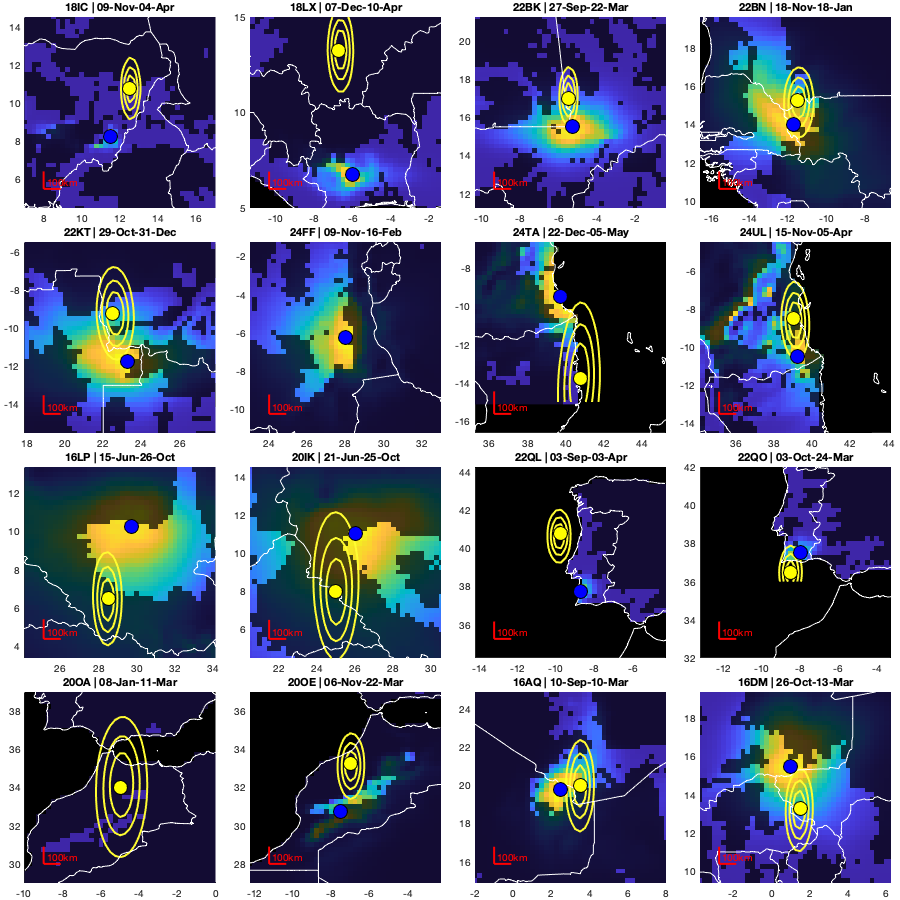

dpptl=nan(height(tblLog),3);

figure('position',[0 0 900 900]);
tiledlayout('flow','TileSpacing','tight','Padding','tight')

for lt=1:height(tblLog)
    iws=find(sta{lt}.status=="wintering");
    if ~isempty(iws)
        nexttile; set(gca,'Color','k'); hold on;
        [gLON,gLAT] = meshgrid(lon{lt},lat{lt});

        tmp_p = pres_prob{lt}(:,:,iws);
        tmp_pt = pres_thr{lt}(:,:,iws);
        tmp_l = light_prob{lt}(:,:,iws);


        [~,id_l]=max(tmp_l(:));
        [~,id_ppt]=max(tmp_p(:).*tmp_pt(:));
        [~,id_lppt]=max(tmp_p(:).*tmp_l(:).*tmp_pt(:));

        dpptl(lt,1) = lldistkm([gLAT(id_l) gLON(id_l)], [gLAT(id_ppt) gLON(id_ppt)]);
        dpptl(lt,2) = sta{lt}.twlNb(iws)/2;
        dpptl(lt,3) = days(sum(~isnan(raw{lt}.pressure.obs(raw{lt}.pressure.date > sta{lt}.start(iws) & raw{lt}.pressure.date < sta{lt}.end(iws))))*diff(raw{lt}.pressure.date(1:2)));


        mask = 0.3+0.7*double(tmp_pt);
        mask(mask_water{lt}) = 0;
        img_tmp = real2rgb(tmp_p,colormap);
        img_tmp = img_tmp.*mask;

        h0=imagesc(lon{lt},lat{lt},img_tmp);
        c_axis=caxis();
        [~,h1]=contour(lon{lt},lat{lt},tmp_l,3,'color',[255, 252, 49]/255,'linewidth',2);

        caxis(c_axis);
        borders('countries','w')

        tt = raw{lt}.GDL_ID + " | ";
        % tt = tt+ num2str(sta{lt}.twlNb(iws))+"twls" + " | ";
        tt = tt + datestr(sta{lt}.start(iws),'dd-mmm');
        tt = tt + "-" + datestr(sta{lt}.end(iws),'dd-mmm');
        title(tt)

        h2=scatter(gLON(id_l), gLAT(id_l),200,'MarkerFaceColor','y','MarkerEdgecolor','k');
        h3=scatter(gLON(id_ppt), gLAT(id_ppt),200,'MarkerFaceColor','b','MarkerEdgecolor','k');
        h4=plot(raw{lt}.calib.lon,raw{lt}.calib.lat,'xr','linewidth',2);

        if tblLog.GDL_ID{lt}=="20OA"
            x00 = [gLON(id_l) gLAT(id_l)];
        elseif tblLog.GDL_ID{lt}=="24FF"
            x00 = [gLON(id_ppt) gLAT(id_ppt)];
        else
            x00 = [(gLON(id_l)+gLON(id_ppt))/2 (gLAT(id_l)+gLAT(id_ppt))/2];
        end
        sz_w=5;
        axis equal; axis([x00(1)-sz_w x00(1)+sz_w x00(2)-sz_w x00(2)+sz_w]);

        x0=x00-sz_w+1;
        dx = 1./[lldistkm(x00,x00+[1 0]) lldistkm(x00,x00+[0 1])]*100;
        h=plot([x0(1) x0(1)], [x0(2) x0(2)+dx(2)], '-r', 'LineWidth', 2);%label(h,'100km','location','middle','slope')
        h=plot([x0(1) x0(1)+dx(1)], [x0(2) x0(2)],'-r', 'LineWidth', 2); label(h,'100km')
    end
end

% exportgraphics(gcf,'pressure_light_winter_map.png','Resolution',300)

Average difference

mean(dpptl(~any(tblLog.GDL_ID==["20OA","24FF"],2),1))

ans = 694.9440

min(dpptl(~any(tblLog.GDL_ID==["20OA","24FF"],2),1))
max(dpptl(~any(tblLog.GDL_ID==["20OA","24FF"],2),1))

## Figure 5

sta_sm=cell(1,height(tblLog));
for lt=1:height(tblLog)
    grp_id = hours(sta{lt}.end-sta{lt}.start)>24;%sta{lt}.twlNb>=4;
    grp_id(1) = true;
    if ~isnat(tblLog.CalibSecondStart(lt))
        grp_id(end) = true;
    end
    sta_sm{lt} = sta{lt}(grp_id,:);
    sta_sm{lt}.actNb =  splitapply(@sum, sta{lt}.actNb,cumsum(grp_id));
    sta_sm{lt}.actEffort =  splitapply(@sum, sta{lt}.actEffort,cumsum(grp_id));
    sta_sm{lt}.actDuration =  splitapply(@sum, sta{lt}.actDuration,cumsum(grp_id));
    sta_sm{lt}.twlNbStopover =  splitapply(@sum, sta{lt}.twlNb,cumsum(grp_id))-sta_sm{lt}.twlNb;
    sta_sm{lt}.staID = find(grp_id);
end

for lt=1:height(tblLog)
 
     figure('position',[0 0 1200 750], 'Name', [raw{lt}.GDL_ID ' | ' tblLog.CommonName{lt}] );
     tiledlayout('flow','TileSpacing','tight','Padding','tight')
    
    [gLON,gLAT] = meshgrid(lon{lt},lat{lt});
    
    mvt_pdf = movementModel('energy',tblLog.mass(lt),tblLog.wingSpan(lt));
    
    for i_s = 1:height(sta_sm{lt}) %find(sta_sm{lt}.status=="wintering")%
        % axes(ha(i_s))
        nexttile; hold on;
        
        % figure('position',[0 0 1600 900]); hold on ; xticks([]); yticks([])
        
        %set(gca,'Color','k')
        tmp_p = pres_prob{lt}(:,:,sta_sm{lt}.staID(i_s));
        tmp_pt = pres_thr{lt}(:,:,sta_sm{lt}.staID(i_s));
        tmp_l = light_prob{lt}(:,:,sta_sm{lt}.staID(i_s));
        
        mask = 0.3+0.7*double(tmp_pt);
        mask(mask_water{lt}) = 0;
        img_tmp = real2rgb(tmp_p,colormap);
        img_tmp = img_tmp.*mask;
        
        imagesc(lon{lt},lat{lt},img_tmp)
        borders('countries','w')
        c_axis=caxis();
        contour(lon{lt},lat{lt},tmp_l,2,'color',[255, 252, 49]/255,'linewidth',2);
        
        tt = datestr(sta_sm{lt}.start(i_s),'dd-mmm HH:MM') + " to " + datestr(sta_sm{lt}.end(i_s),'dd-mmm HH:MM');
        % tt = tt+ " (pres.: "+ num2str(pres_n{lt}(i_s)) + " hrs, light: "+ num2str(sta_sm{lt}.twlNb(i_s) + " twls)");
        
        if i_s>1
            tt = tt+ " | flight: "+num2str(round(hours(sta_sm{lt}.actEffort(max(1,i_s-1))))) + " hrs"  ;
%             if exist('path','var')
%                 path_mean(i_s,:) = median([gLON(path{lt}(sta_sm{lt}.staID(i_s),:)') gLAT(path{lt}(sta_sm{lt}.staID(i_s),:)')]);
%                 tmpd = reshape(lldistkm([path_mean(i_s-1,2) path_mean(i_s-1,1)],[gLAT(:) gLON(:)]),size(gLAT))./hours(sta_sm{lt}.actEffort(i_s-1));
%                 plot(path_mean(i_s-1,1), path_mean(i_s-1,2),'ow','MarkerSize',8,'markerFaceColor','g','linewidth',3)
%                 plot(path_mean(i_s,1), path_mean(i_s,2),'or','linewidth',2,'MarkerSize',8)
%             else
%                 tmpd = reshape(lldistkm([gLAT(id) gLON(id)],[gLAT(:) gLON(:)]),size(gLAT))./hours(sta_sm{lt}.actEffort(i_s-1));
%                 plot(gLON(id), gLAT(id),'ow','MarkerSize',8,'markerFaceColor','g','linewidth',3)
%                 [~,id]=max(tmp_p(:).*tmp_pt(:).*tmp_l(:).*mvt_pdf(tmpd(:)));
%                 plot(gLON(id), gLAT(id),'or','linewidth',2,'MarkerSize',8)
%             end
%            contour(lon{lt},lat{lt},tmpd,[7 17]/1000*60*60,'-g','linewidth',2); % ,'ShowText','on'
            
        else
%             clear path_mean
%             path_mean(i_s,:) = median([gLON(path{lt}(sta_sm{lt}.staID(i_s),:)') gLAT(path{lt}(sta_sm{lt}.staID(i_s),:)')]);
%             [~,id]=max(tmp_p(:).*tmp_pt(:).*tmp_l(:));
%             plot(gLON(id), gLAT(id),'or','linewidth',2,'MarkerSize',8)
        end

        % t=text(.01,.8,tt,'Units','normalized','FontSize',40,'FontWeight','bold','Color','w','VerticalAlignment','top');

        title(tt)

        caxis(c_axis);
        
        plot(raw{lt}.calib.lon,raw{lt}.calib.lat,'ow','MarkerSize',6,'markerFaceColor','r')
        
        axis equal; axis([min(lon{lt}) max(lon{lt}) min(lat{lt}) max(lat{lt}) ]);
        set(gca,'ydir','normal');
        yticks([]);xticks([])
        
%         x0=[raw{lt}.calib.lon-4 raw{lt}.calib.lat-4];
%         dx = 1./[lldistkm(x0,x0+[1 0]) lldistkm(x0,x0+[0 1])]*100;
%         h=plot([x0(1) x0(1)], [x0(2) x0(2)+dx(2)], '-r', 'LineWidth', 2);%label(h,'100km','location','middle','slope')
%         h=plot([x0(1) x0(1)+dx(1)], [x0(2) x0(2)],'-r', 'LineWidth', 2); label(h,'100km')
%         
        % exportgraphics(gcf,['combined_map_' tblLog.CommonName{lt} '_' raw{lt}.GDL_ID '_' num2str(i_s) '.png'],'Resolution',600)
        %keyboard
        % close all
        
    end
     
    exportgraphics(gcf,['combined_map_24h_' tblLog.CommonName{lt} '_' raw{lt}.GDL_ID '.png'],'Resolution',300)
close all
end

A=flipud([imread('../data/DEM/land_shallow_topo_west.tif') imread('../data/DEM/land_shallow_topo_east.tif')]);
y=linspace(-180,180,size(A,2));
x=linspace(-90,90,size(A,1));
A2 = A(x>=min(glat) & x<=max(glat) , y>=min(glon) & y<=max(glon),:);
x2=x(x>=min(glat) & x<=max(glat));
y2=y(y>=min(glon) & y<=max(glon));

figure; hold on
imagesc(y2,x2,A2); axis equal tight; set(gca,'ydir','normal')

% axis([min(lon{lt}) max(lon{lt}) min(lat{lt}) max(lat{lt}) ]);

for lt=1:height(tblLog)
    a = pres_thr{lt}(:,:,sta{lt}.status=="wintering").*pres_prob{lt}(:,:,sta{lt}.status=="wintering");
    a = a./ sum(a(:));
    [as,asid]=sort(a(:));
    tmp_m=true(size(a));
    % tmp_m(asid(cumsum(as)<.8))=true;
    th=as(find(cumsum(as)>.1,1));
    % tmp_m(asid(cumsum(as)<.1))=false;
    
   
    [~,id_ppt]=max(a(:));

    [gLON,gLAT] = meshgrid(lon{lt},lat{lt});

    plot(gLON(id_ppt),gLAT(id_ppt),'ow','MarkerFaceColor',tblLog.Color(lt,:))
    
    imcontour(gLON,gLAT,a,2,'Color',tblLog.Color(lt,:),'linewidth',4)
     %P = mask2poly(tmp_m');
    
%     for i_p=1:numel(P)
%             plot(lon{lt}(P(i_p).Y),lat{lt}(P(i_p).X),'Color',tblLog.Color(lt,:),'LineWidth',2)
%            
% %             if lt==7 | lt==8 | lt==11
% %                 wmpolygon((lat{lt}(P(i_p).X)),(lon{lt}(P(i_p).Y)),'EdgeColor',tblLog.Color(lt,:),'FaceAlpha',0,'LineWidth',2)
% %             else
% %                  end
%     end
    % keyboard
end

Webmap

webmap('worldimagery')

for lt=1:height(tblLog)
    if lt==11 | lt==12
        continue
    end
    a = pres_thr{lt}(:,:,sta{lt}.status=="wintering").*pres_prob{lt}(:,:,sta{lt}.status=="wintering");
    a = a./ sum(a(:));
    [as,asid]=sort(a(:));
    tmp_m=false(size(a));
    % tmp_m(asid(cumsum(as)<.8))=true;
    tmp_m(asid(cumsum(as)<.9))=true;
    
    P = mask2poly(tmp_m');
    
    [~,id_ppt]=max(a(:));

    [gLON,gLAT] = meshgrid(lon{lt},lat{lt});

    wmmarker(gLAT(id_ppt),gLON(id_ppt),'Color',tblLog.Color(lt,:))
    
    for i_p=1:numel(P)
        if P(i_p).Length>5
            if lt==7 | lt==8 | lt==11
                wmpolygon((lat{lt}(P(i_p).X)),(lon{lt}(P(i_p).Y)),'EdgeColor',tblLog.Color(lt,:),'FaceAlpha',0,'LineWidth',2)
            else
                wmpolygon(flipud(lat{lt}(P(i_p).X)),flipud(lon{lt}(P(i_p).Y)),'EdgeColor',tblLog.Color(lt,:),'FaceAlpha',0,'LineWidth',2)
            end
        end
    end
    % keyboard
end

% Export geotif
% for lt=1:height(tblLog)
%     A = pres_thr{lt}(:,:,iws).*res_prob{lt}(:,:,iws);
%     R = georasterref('RasterSize',size(A),'LatitudeLimits',[min(lat{lt}),max(lat{lt})],'LongitudeLimits',[min(lon{lt}),max(lon{lt})]);
%     geotiffwrite(['pressure_winter_map_' raw{lt}.GDL_ID '.tif' ],A./ sum(A(:)),R)
% end